% This is for Task 8

% For this task I will use the bag of words used to create the 
% best LSA model. 

% The next few lines create the LDA model. I am also iteratively creating
% the best module by following the guide found here: 
% https://uk.mathworks.com/help/textanalytics/ug/choose-number-of-topics-for-LDA-model.html

% The next two lines load the reviews again into a variable to ensure no
% issues or changes occured in previous tasks
file_to_load = "JewelleryReviewsLSA.csv";
reviews_final = readtable(file_to_load,'TextType', 'string');

% The next two lines creates an unneeded bag of words so that the reviews
% can be pre processed using the self defined function. Remember that the
% bag is needed so that the preprocessText function will work. I remember
% that there is no missing data so dont need to remove any rows or check
% for missing values. 
intialized_bag = bagOfWords(tokenizedDocument(reviews_final.Reviews));
reviews = preprocessText(reviews_final.Reviews,intialized_bag);

terms_2 = 1386

number_of_terms_removed_by2 = 0

terms_3 = 1375

number_of_terms_removed_by3 = 11

terms_4 = 1188

number_of_terms_removed_by_4 = 187

terms_5 = 968

number_of_terms_removed_by5 = 220

terms_6 = 955

number_of_terms_removed_by6 = 13

terms_7 = 919

number_of_terms_removed_by7 = 36

terms_8 = 918

number_of_terms_removed_by8 = 1

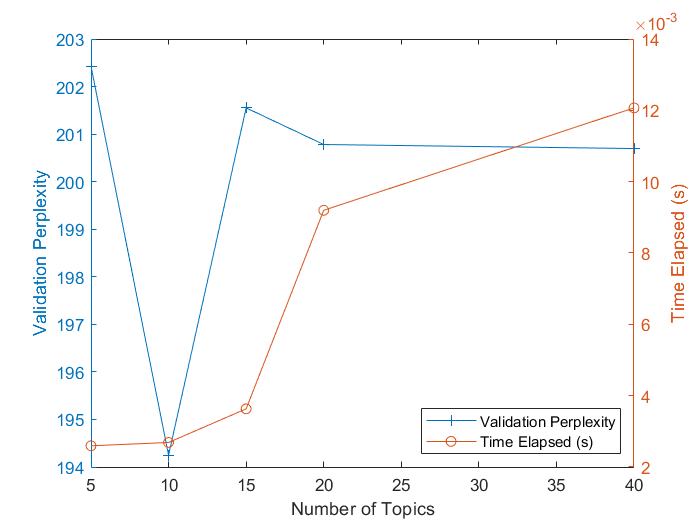



% The next block of code is used to split the reviews into training and
% testing data to optimize the LDA model. The rng is used to ensure
% reproducability. 
rng(42);
numReviews = numel(reviews);
cvp = cvpartition(numReviews,'HoldOut',0.1);
reviewsTrain = reviews(cvp.training);
reviewsValidation = reviews(cvp.test);

% This line creates a bag of words out of the training reviews. A new bag
% is needed as using bag_task_4 for creation would not have any validtion
% sets in it. 
bag_training = bagOfWords(reviewsTrain);

% This for loop iteratively creates an LDA model and stores the results 
% to understand what the best number of topics for the model is
numTopicsRange = [5 10 15 20 40];
for i = 1:numel(numTopicsRange)
    numTopics = numTopicsRange(i);
    
    mdl_LDA = fitlda(bag_training,numTopics, ...
        'Solver','savb', ...
        'Verbose',0);
    
    [~,validationPerplexity(i)] = logp(mdl_LDA,reviewsValidation);
    timeElapsed(i) = mdl_LDA.FitInfo.History.TimeSinceStart(end);
end

% This plots the perplexity of the LDA models to determine what the best
% number of topics is. 
figure
yyaxis left
plot(numTopicsRange,validationPerplexity,'+-')
ylabel("Validation Perplexity")

yyaxis right
plot(numTopicsRange,timeElapsed,'o-')
ylabel("Time Elapsed (s)")

legend(["Validation Perplexity" "Time Elapsed (s)"],'Location','southeast')
xlabel("Number of Topics")

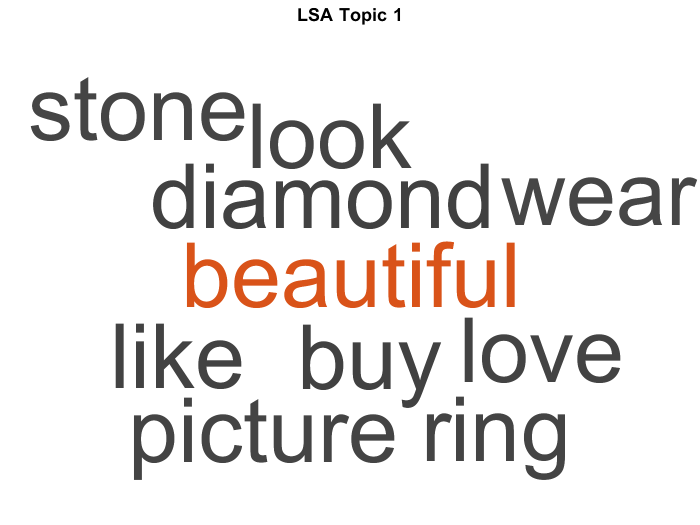

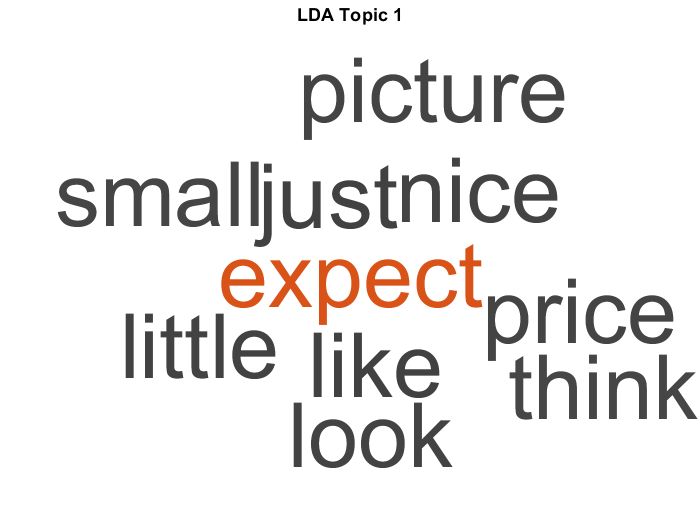

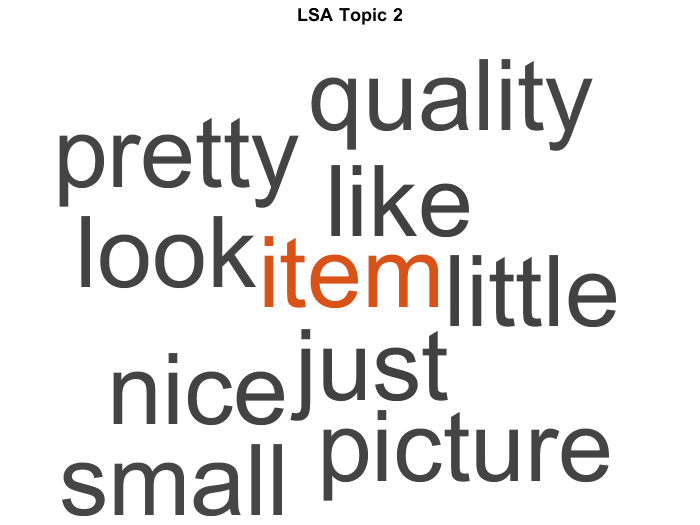

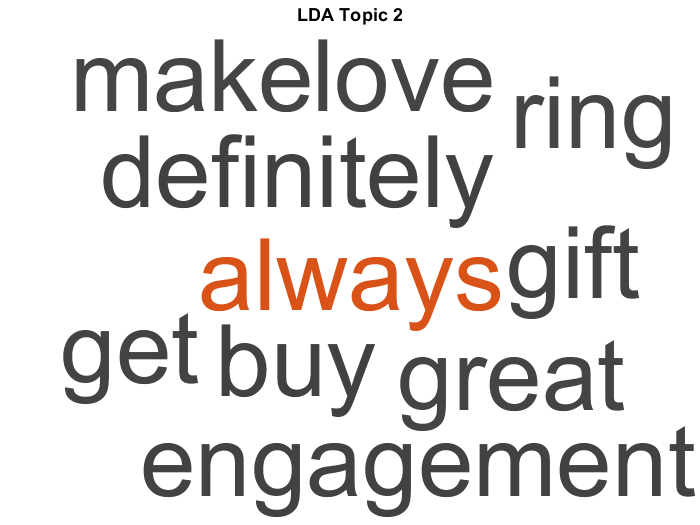

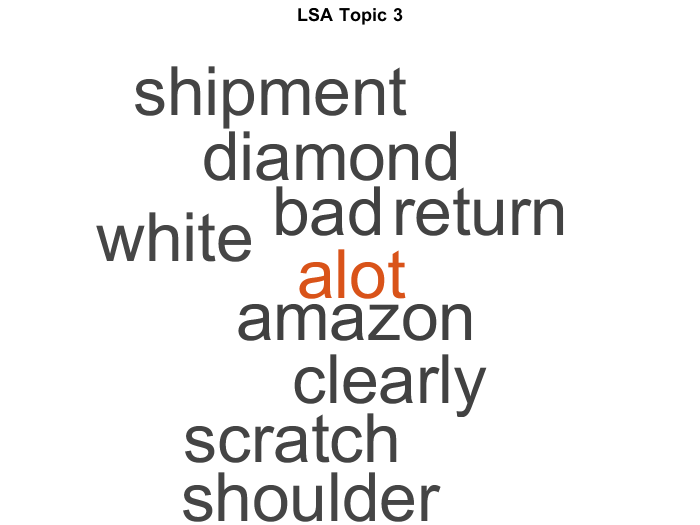

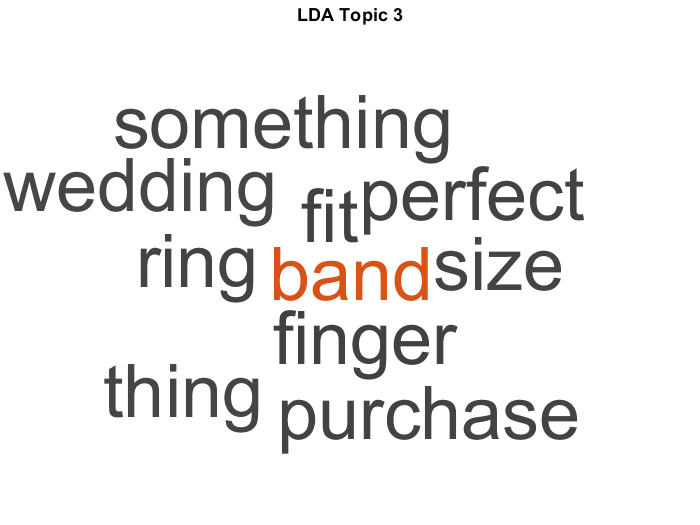

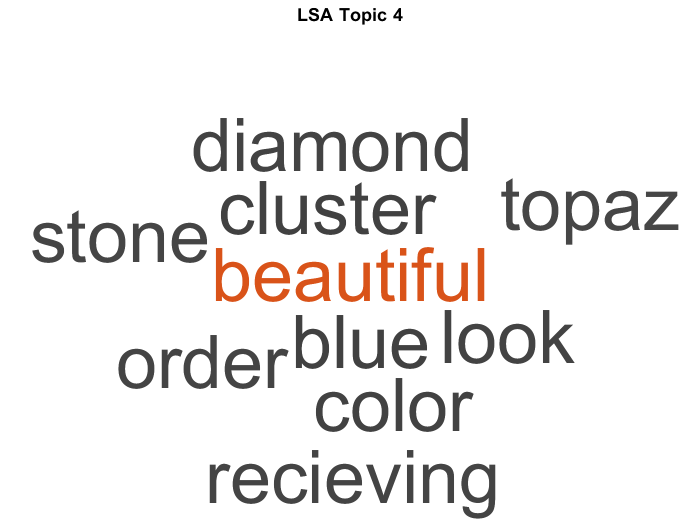

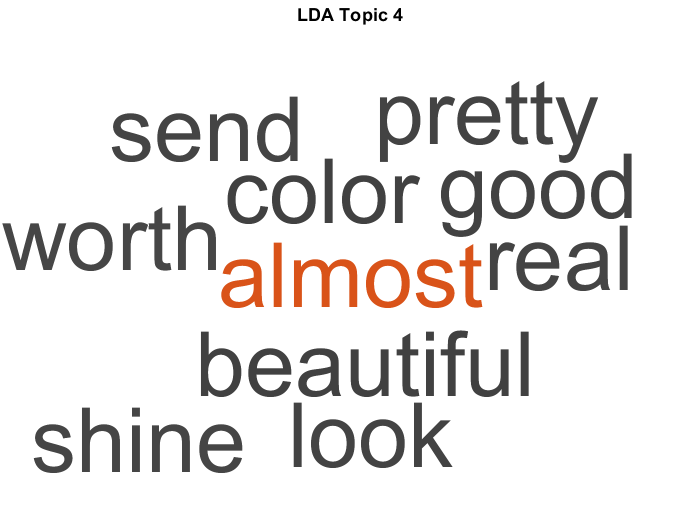

% Inspecting the plot I can see that the best number of topics 
% is 10.

% This creates an LDA model with 10 topics. As mentioned earlier
% It needs to use the same bag used to create the best LSA model
% That is why it uses bag_task_4
final_LDA_mdl = fitlda(bag_task_4,10,'Verbose',0);

% This creates a new LSA model which has same number of topics/components
% as the ABove LDA model
newLSA = fitlsa(bag_task_4,10);

% This access the word scores so that we can see the words and how
% correlated they are with a topic. WordScores(i,j) is how strongly 
% Word i is associated with topic j. 
wordScores = newLSA.WordScores;

% These two lines create two empty matrices that are 10x10(10 words by 10
% topics). Each column of the matrix is the 10 words most strongly
% associated with  topic i. 
top_words_LSA = strings(10,10);
top_words_LDA = strings(10,10);
% This creates empty matrices to hold the words so that
% Tsne can be used to plot and compare the two models. 


% This loops over all 10 topics(the columns of the 
% wordScores matrix and puts the top 10 words associated with
% it in a word cloud for visualization. It also saves the top 10 words to a
% vector so that they can be exported to the report
for i =1:10
    % THe next portion finds the top 10 words associated with the topic in
    % question(topic i). It gets the index of the top 10 words most
    % strongly associated with topic i. Then accesses then vocabulairy of
    % the LSA model to find the word itself. It also saves the top words to
    % the required matrix
    [top_words, index_of_top_words] = maxk(wordScores(:,i),10);
    words_final_LSA = newLSA.Vocabulary(index_of_top_words);
   top_words_LSA(:,i)= words_final_LSA;
    top_words_LSA_Numbers(:,1) = top_words;
    
    % THis plots the top 10 words of each topic associated in the LSA as a
    % word cloud
    figure
    wordcloud(words_final_LSA)
    title("LSA Topic " + i)
    % This computes the top 10 words from the LDA model using the 
    % Correct matrices associated with it. 
    [words_LDA, index_of_top_words_LDA] = maxk(final_LDA_mdl.TopicWordProbabilities(:,i),10);
    words_final_LDA = final_LDA_mdl.Vocabulary(index_of_top_words_LDA);
    top_words_LDA(:,i)= words_final_LDA;
    
    % This plots the top 10 words from the LDA MODEL for each topic
 
    figure
    wordcloud(words_final_LDA);
    title("LDA Topic " + i)
end


% Creating column names for the tables to output. 
ColumnNames = ["Topic 1", "Topic 2",...
    "Topic 3", "Topic 4", "Topic 5","Topic 6", "Topic 7","Topic 8", ...
    "Topic 9","Topic 10"];

% These lines output the LDA and LSA tables. 
LDA_table = array2table(top_words_LDA,"VariableNames",ColumnNames)

LDA_table = 10×10 table
     Topic 1       Topic 2         Topic 3        Topic 4       Topic 5        Topic 6          Topic 7         Topic 8        Topic 9       Topic 10  
    _________    ____________    ___________    ___________    _________    _____________    _____________    ____________    _________    ____________

    "look"       "ring"          "ring"         "look"         "receive"    "wear"           "quality"        "ring"          "ring"       "bracelet"  
    "like"       "love"          "size"         "beautiful"    "time"       "want"           "item"           "stone"         "diamond"    "poor"      
    "picture"    "buy"     

LSA_table = array2table(top_words_LSA,"VariableNames",ColumnNames)

LSA_table = 10×10 table
      Topic 1       Topic 2      Topic 3        Topic 4       Topic 5        Topic 6       Topic 7      Topic 8        Topic 9      Topic 10
    ___________    _________    __________    ___________    __________    ___________    _________    __________    ___________    ________

    "ring"         "look"       "diamond"     "blue"         "wear"        "item"         "item"       "bracelet"    "beautiful"    "silver"
    "look"         "like"       "return"      "topaz"        "diamond"     "quality"      "like"       "purchase"    "color"        "great" 
    "diamond"      "picture"    "shoulder"    "cluster"      "quality" 